# Laboratorio 2

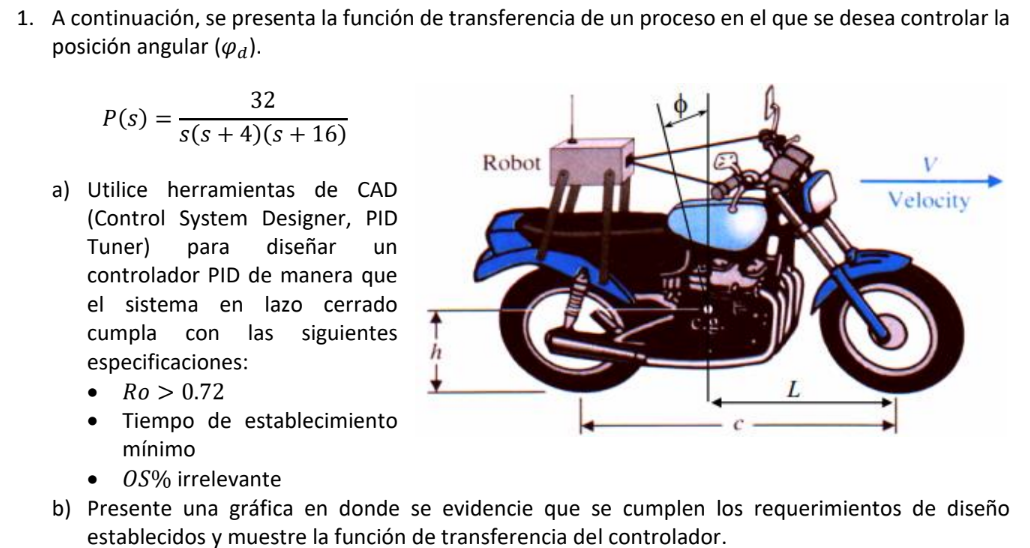

load C.mat
s = tf('s');

P2 = 32/(s*(s+4)*(s+16))


P2 =
 
          32
  -------------------
  s^3 + 20 s^2 + 64 s
 
Continuous-time transfer function.
Model Properties


P_2 = feedback(P2,1)


P_2 =
 
             32
  ------------------------
  s^3 + 20 s^2 + 64 s + 32
 
Continuous-time transfer function.
Model Properties


% PI
C_pi_2


C_pi_2 =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 5.75, Ki = 0.245
 
Continuous-time PI controller in parallel form.
Model Properties


P2C_pi = feedback(P2*C_pi_2,1);
% PID
C_pid_2


C_pid_2 =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 8.24, Ki = 0.492, Kd = 4.27, Tf = 0.00124
 
Continuous-time PIDF controller in parallel form.
Model Properties


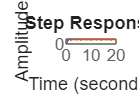

P2C_pid = feedback(P2*C_pid_2,1);
step(P2C_pi,P2C_pid)

stepinfo([P2C_pi P2C_pid])

ans = 1×2 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


# Experimento del Relé

### Astrom Huggled

c) Utilice SIMULINK® para aplicar el experimento del relé al proceso y diseñe un controlador PID aplicando las reglas de Åström-Hägglund (AH).

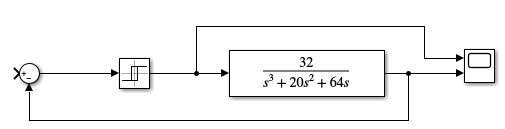

d) Presente una gráfica en donde se evidencie la respuesta del sistema en lazo cerrado usando este controlador y muestre la función de transferencia del controlador.

d = 1

d = 1

PM = 47 %Margen de fase 

PM = 47

Tc = 807.65e-3 %Este periodo critico lo definimos en el scope en simulink

Tc = 0.8076

A = 3.346e-2 %Amplitud

A = 0.0335

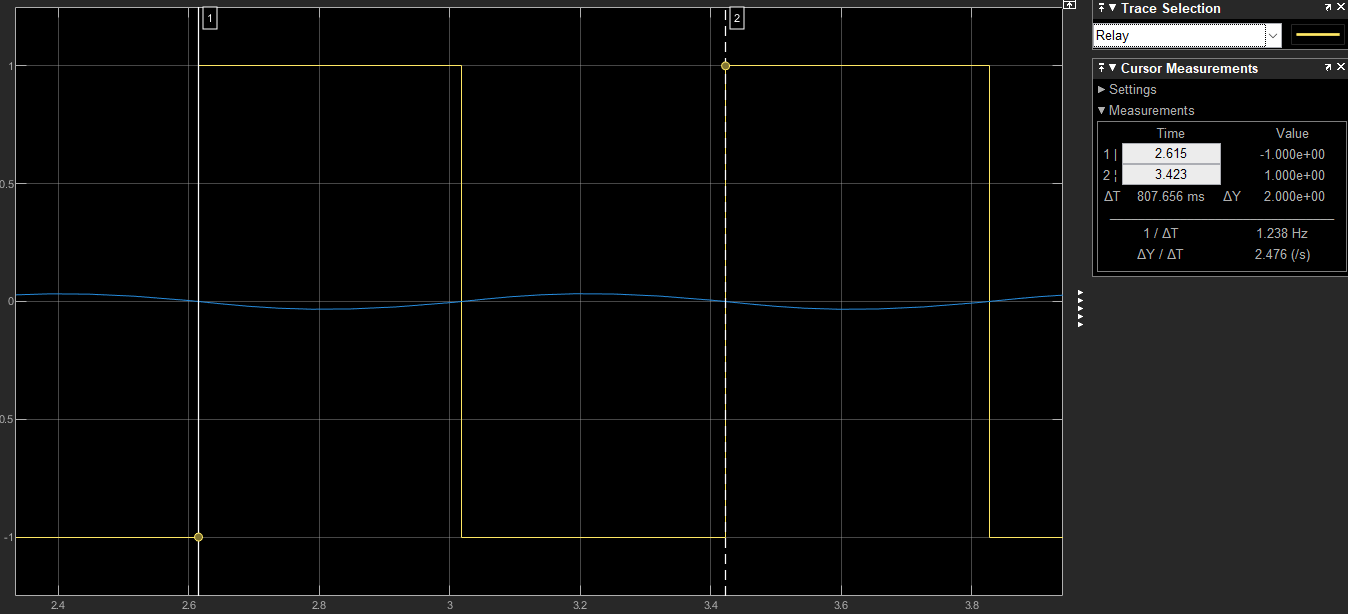

%Ec. de Astrom Huggled
Tao_d = ((PM-37)/360)*Tc

Tao_d = 0.0224

KC_AH = (4*d)/(pi*A)

KC_AH = 38.0526

KP_AH=0.6*KC_AH

KP_AH = 22.8316

TI_AH=0.5*Tc

TI_AH = 0.4038

TD_AH=0.125*Tc

TD_AH = 0.1010

C_AH=zpk(KP_AH*(1+1/(TI_AH*s)+TD_AH*s))% TF del controlador


C_AH =
 
  2.305 (s+4.953)^2
  -----------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


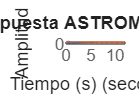

 % Convertir a función de transferencia

% Sistema en lazo cerrado
T = feedback(C_AH * P2, 1);

% Gráfica de la respuesta al escalón
figure;
step(P_2,T);
title('Respuesta ASTROM HUGLED');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;


% Información de la respuesta
info = stepinfo(T);
disp('Información de la respuesta AH:');

Información de la respuesta AH:


disp(info);

         RiseTime: 0.1677
    TransientTime: 2.7986
     SettlingTime: 2.7986
      SettlingMin: 0.7386
      SettlingMax: 1.5935
        Overshoot: 59.3525
       Undershoot: 0
             Peak: 1.5935
         PeakTime: 0.4801




% Mostrar la función de transferencia del controlador
disp('Función de transferencia del controlador:');

Función de transferencia del controlador:


C_AH


C_AH =
 
  2.305 (s+4.953)^2
  -----------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


e) Utilice SIMULINK® para aplicar el experimento del relé al proceso y diseñe un controlador PID

aplicando las reglas de Kaiser-Chiara (KC). Utilice un margen de fase de 47°.

f) Presente una gráfica en donde se evidencie la respuesta del sistema en lazo cerrado usando este

controlador y muestre la función de transferencia del controlador.

### Kaiser-Chiara

kc_kc=(4*d)/(pi*A)

kc_kc = 38.0526

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


kp_kc= kc_kc*cosd(PM)

kp_kc = 25.9518

Ti_kc=Tc*((1+sind(PM))/(pi*cosd(PM)))

Ti_kc = 0.6526

Td_kc=0.25*Ti_kc

Td_kc = 0.1632

C_kc=zpk(kp_kc*(1+1/(Ti_kc*s)+Td_kc*s))


C_kc =
 
  4.2343 (s+3.064)^2
  ------------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


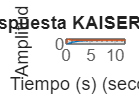


% Sistema en lazo cerrado
T = feedback(C_kc * P2, 1);

% Gráfica de la respuesta al escalón
figure;
step(P_2,T);
title('Respuesta KAISER CHIARA');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;


% Información de la respuesta
info = stepinfo(T);
disp('Información de la respuesta KC:');

Información de la respuesta KC:


disp(info);

         RiseTime: 0.1430
    TransientTime: 1.0292
     SettlingTime: 1.0292
      SettlingMin: 0.9208
      SettlingMax: 1.2918
        Overshoot: 29.1829
       Undershoot: 0
             Peak: 1.2918
         PeakTime: 0.3658




% Mostrar la función de transferencia del controlador
disp('Función de transferencia del controlador:');

Función de transferencia del controlador:


C_kc


C_kc =
 
  4.2343 (s+3.064)^2
  ------------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


### Kaiser Rajka

g) Utilice SIMULINK® para aplicar el experimento del relé al proceso y diseñe un controlador PID

aplicando las reglas de Kaiser-Rajka (KR). Utilice un margen de fase de 47°.

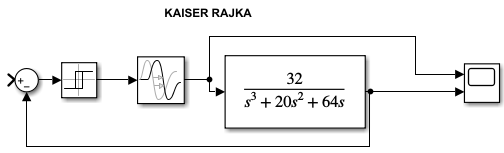

h) Presente una gráfica en donde se evidencie la respuesta del sistema en lazo cerrado usando este

controlador y muestre la función de transferencia del controlador.

% 1er iteración = 968ms 1.011
Tc_kr= 1.016

Tc_kr = 1.0160

PM=47

PM = 47

Tao_d= ((PM-37)/360)*Tc_kr

Tao_d = 0.0282

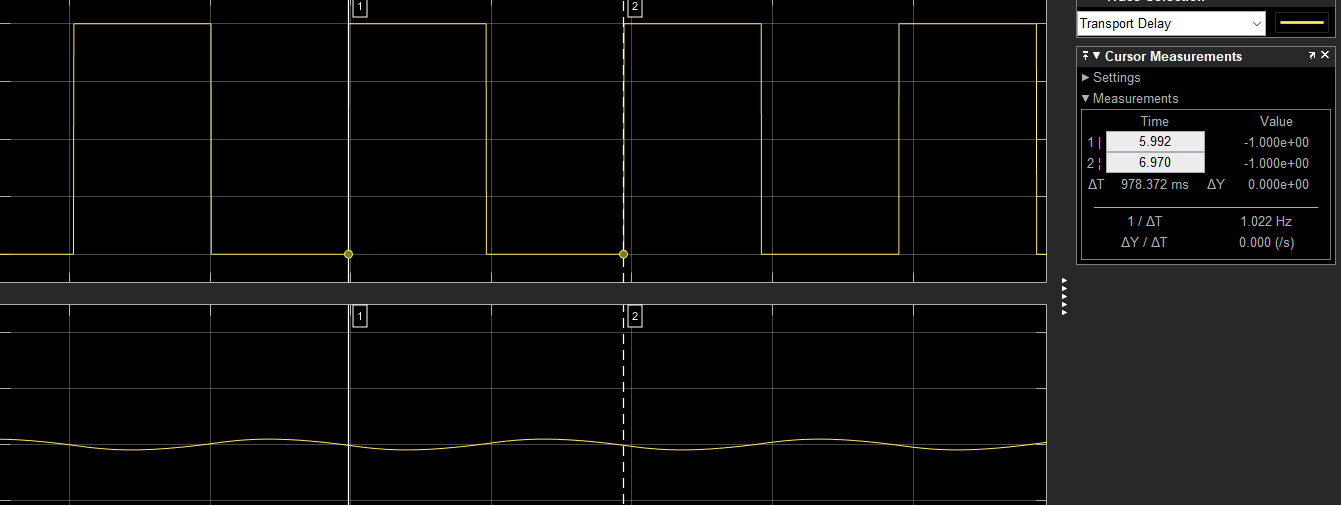

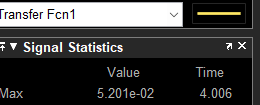

a_kr=5.201e-2

a_kr = 0.0520

kc_kr=(4*d)/(pi*a_kr)

kc_kr = 24.4807

%Tomamos las ecuaciones de Kaiser Rajka
kp_kr=0.8*kc_kr

kp_kr = 19.5845

Ti_kr=0.64*Tc_kr

Ti_kr = 0.6502

Td_kr=0.16*Tc_kr

Td_kr = 0.1626

s=tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


C_kr=zpk(kp_kr*(1+1/(Ti_kr*s)+Td_kr*s))


C_kr =
 
  3.1837 (s+3.076)^2
  ------------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


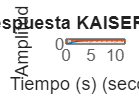


% Sistema en lazo cerrado
T = feedback(C_kr * P2, 1);

% Gráfica de la respuesta al escalón
figure;
step(P_2,T);
title('Respuesta KAISER RAJKA');
xlabel('Tiempo (s)');
ylabel('Amplitud');
grid on;


% Información de la respuesta
info = stepinfo(T);
disp('Información KR');

Información KR


disp(info);

         RiseTime: 0.1759
    TransientTime: 1.1106
     SettlingTime: 1.1106
      SettlingMin: 0.9104
      SettlingMax: 1.2956
        Overshoot: 29.5560
       Undershoot: 0
             Peak: 1.2956
         PeakTime: 0.4692




% Mostrar la función de transferencia del controlador
disp('FT controlador KR:');

FT controlador KR:


C_kr


C_kr =
 
  3.1837 (s+3.076)^2
  ------------------
          s
 
Continuous-time zero/pole/gain model.
Model Properties


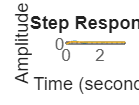

P_AH = feedback(P2*C_AH,1);
P_kc = feedback(P2*C_kc,1);
P_kr = feedback(P2*C_kr,1);
step(P_AH,P_kc,P_kr)

stepinfo([P_AH P_kc P_kr])

ans = 1×3 struct array with fields:
    RiseTime
    TransientTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


% Datos de ejemplo

Nombre = ["kp"; "Ti"; "Td"; "K"; "Z1"; "Z2"];

Valor = [23.5; 45.7; 18.9];

Unidad = ["°C"; "°C"; "°C"];

% Crear la tabla

T = table(Nombre, Valor, Unidad);

% Mostrar la tabla

disp(T)